# **制御器の付加**

**本ファイルでは電力システムにコントローラをつけてシミュレーションを行う方法を説明します。**

**制御器を付加せずに各種解析を行う場合は本stepはスキップして構いません。**

**以下の赤枠で囲った部分の作業に対応します。**

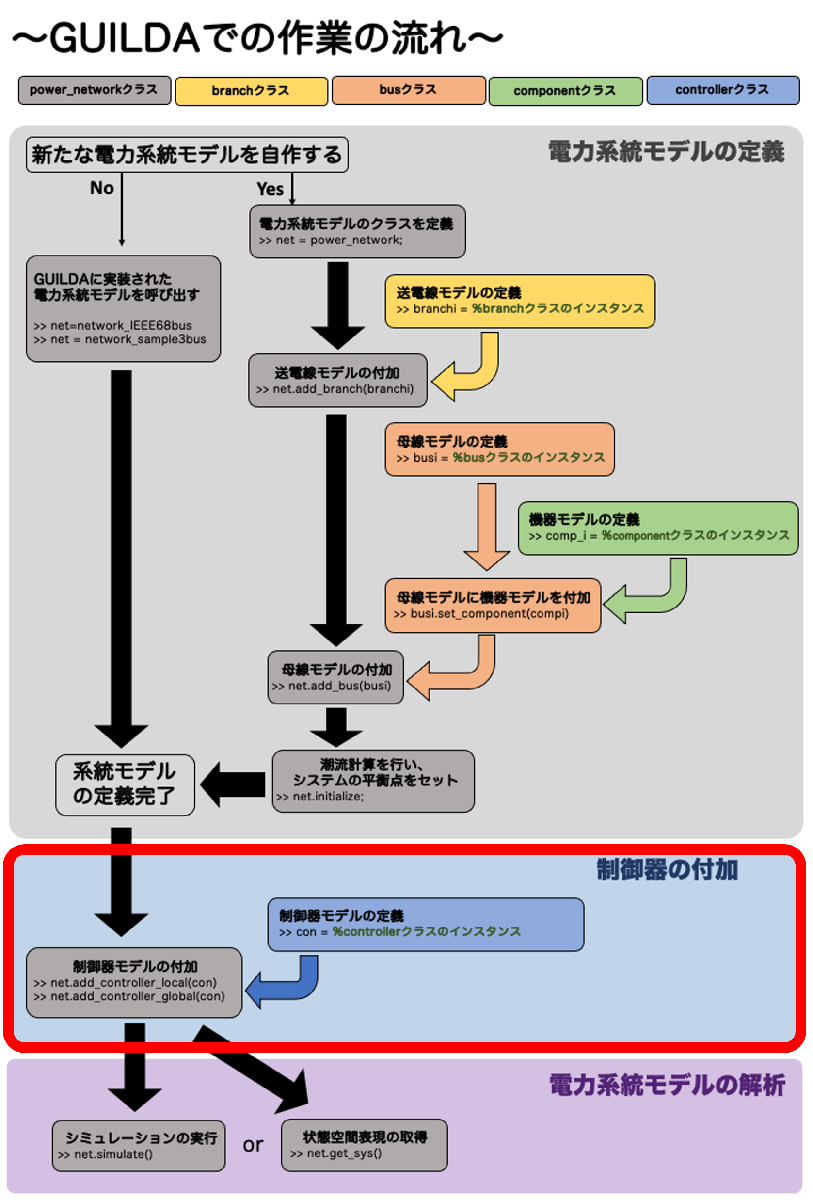

## **電力ネットワークの定義**

ひとまずシミュレーション対象となる電力ネットワークを作成します。

詳しくは、「[Step1_BuildNetwork](matlab:open('./Step1_BuildNetwork.mlx'))」を参照してください。

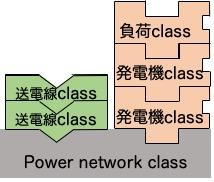

### ・実装方法

 
% IEEE68busモデルを使用
net = network.IEEE68bus;

**~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~**

## **~~コントローラを指定する際には、キーを指定する~~**

**~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~**

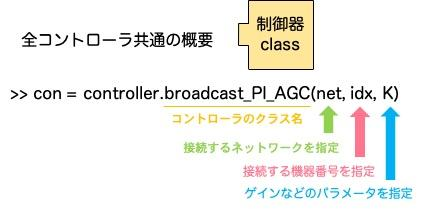

### ・コントローラの種類

- AGCコントローラ：詳しくは「[Controller_AGC](matlab:open('./ClassManual/Controller_AGC.mlx'))」を参照

- LQRコントローラ：詳しくは「[Controller_LQR](matlab:open('./ClassManual/Controller_LQR.mlx'))」を参照

- レトロフィットコントローラ：詳しくは「[Controller_Retrofit](matlab:open('./ClassManual/Controller_Retrofit.mlx'))」を参照

- 自分でコントローラを作る：詳しくは「[Controller_Abstract](matlab:open('./ClassManual/Controller_Abstract.mlx'))」を参照

## **コントローラの付加**

作成したコントローラを電力ネットワークに付加します。

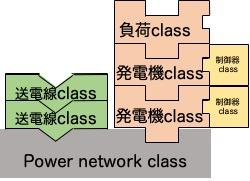

### ・実装方法

 
% 制御器を付加する
net.add_controller_global(con);

## ローカルコントローラの付加

ローカルコントローラに関しては以下のように定義を行います。

具体的な引数の内容に関してはドキュメントを参照してください。

a_Comp = net.a_Bus{1}.a_Component{1};
a_Comp.add_local_controller("LQR","parameter",tab);

## グローバルコントローラの付加

グローバルコントローラに関しては以下のように定義を行います。

具体的な引数の内容に関してはドキュメントを参照してください。

a_Comp = tools.cellfun(@(b) b.a_Component{1}, net.a_Bus([1,2,3,6,8]));
net.add_global_controller("AGC", "From", a_Comp{:}, "To", a_Comp{:}, "parameter", tab)

## **シミュレーションの実行**

最後にコントローラをつけた電力ネットワークでシミュレーションを行います。

シミュレーションの実行についての詳細は「[Step3_SimulateCondition](matlab:open('./Step3_SimulateCondition.mlx'))」を、プロットについては「[Step4_SimulateResultData](matlab:open('./Step4_SimulateResultData.mlx'))」を参照してください。

### ・実装方法

 
% シミュレーション
event = odeEventSet("fault",net,"FaultBus","B008","TimeSpan",[3,3.01]);
sol   = net.simulate([0,30],event);
sol   = sol.odeResults;
 
% シミュレーション結果のプロット
out.plot('para', 'omega')

`以上で電力系統モデルを定義し、制御器を付加することができました。`

`次のステップでは、この電力システムの定常潮流状態や平衡点などのデータの読み方を解説します。`

[](matlab:open('./Step1_BuildNetwork.mlx'))　　[](matlab:open('./Step3_NetProperties.mlx'))